# Matlab Graph Matrix with Jet Spectrum Color, Label a Subset Examples

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

## Plot a Subset of Data Matrix with Appropriate Legends

Sometimes we solve a model across many states, but we can only plot at a subset of states, or perhaps we plot at all states, but only show legends/labels for a subset.

In the example below, many lines are plotted, however, only a subset of lines are labeled in the legend.

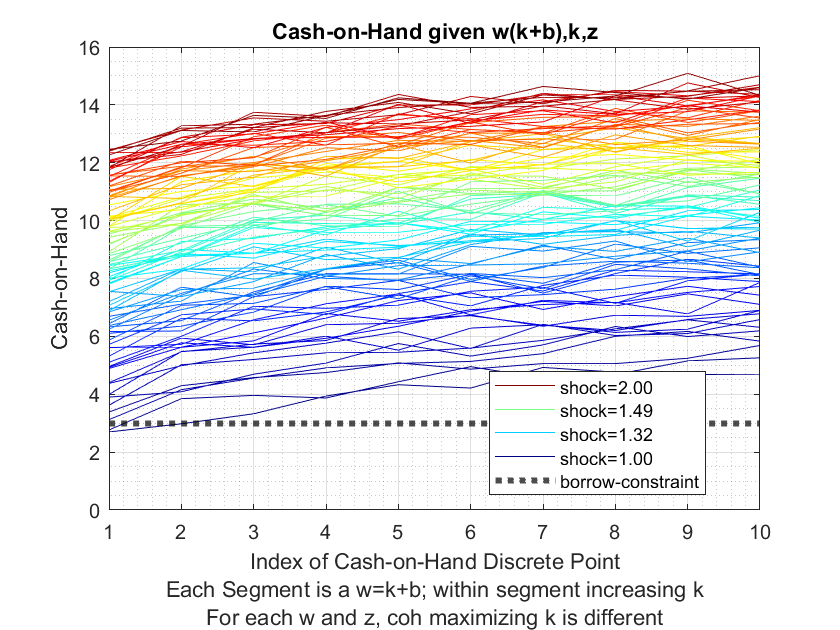

clear all;
close all;

% Generate Random Data
rng(123);
it_x_n = 10;
it_y_groups_n = 100;
ar_y = linspace(1,2,it_y_groups_n);
mat_y = rand([it_x_n, it_y_groups_n]);
mat_y = mat_y + sqrt(1:it_y_groups_n);
mat_y = mat_y + log(1:it_x_n)' + ar_y;
ar_x = 1:1:it_x_n;

% Jet color Graph All
figure('PaperPosition', [0 0 7 4]);
chart = plot(mat_y);
clr = jet(numel(chart));
for m = 1:numel(chart)
    set(chart(m),'Color',clr(m,:))
end

% zero lines
xline(0);
yline(0);

% invalid points separating lines
yline_borrbound = yline(3);
yline_borrbound.HandleVisibility = 'on';
yline_borrbound.LineStyle = ':';
yline_borrbound.Color = 'black';
yline_borrbound.LineWidth = 3;

% Titling
title('Cash-on-Hand given w(k+b),k,z');
ylabel('Cash-on-Hand');
xlabel({'Index of Cash-on-Hand Discrete Point'...
    'Each Segment is a w=k+b; within segment increasing k'...
    'For each w and z, coh maximizing k is different'});

% Xlim controls
xlim([min(ar_x), max(ar_x)]);

% Grid ons
grid on;
grid minor;
% Legends
legend2plot = fliplr([1 round(numel(chart)/3) round((2*numel(chart))/4)  numel(chart)]);
legendCell = cellstr(num2str(ar_y', 'shock=%3.2f'));

legendCell{length(legendCell) + 1} = 'borrow-constraint';
chart(length(chart)+1) = yline_borrbound;
legend(chart([legend2plot length(legendCell)]), ...
       legendCell([legend2plot length(legendCell)]), ...
       'Location', 'best');